# Acquire and Plot Angular Velocity and Orientation Data from Your Mobile Device

This example shows how to plot data from multiple sensors on an Android™ or iOS mobile device together in one timeline. Measurements of angular velocity and orientation will be collected from the device and plotted over absolute time. This will allow correlations between data from two sensors to be visualized based on the actual time of measurement. 

## Set Up Your Mobile Device

In order to receive data from a mobile device in MATLAB®, you will need to install and set up the MATLAB Mobile™ app on your mobile device.

Log in to the MathWorks® Cloud from the MATLAB Mobile Settings.

## Create a Connection to Your Mobile Device

On the **Commands** screen of MATLAB Mobile, use the `mobiledev` command to create an object that represents your mobile device.

m = mobiledev;

The displayed output should show `Connected: 1`, indicating that the  `mobiledev` object has successfully established a connection to the app.

## Prepare for Data Acquisition from Multiple Sensors

Use the appropriate `mobiledev` properties to enable sensors on the device.

m.AngularVelocitySensorEnabled = 1;
m.OrientationSensorEnabled = 1;

## Start Acquiring Data

After enabling the sensors, the **Sensors** screen of MATLAB Mobile will show the current data measured by the sensors. The `Logging` property allows you to begin sending sensor data to `mobiledev`.

m.Logging = 1;

The device is now transmitting sensor data.

At the start of logging, the device is lying flat on a table with the screen facing up. The positive Y-axis of the angular velocity sensor is defined to extend out from the top of the device. Positive roll of the orientation sensor is defined as a clockwise rotation about the Y-axis when facing the positive direction of the axis. 

During logging, the device is turned face-up and face-down a few times about its Y-axis. This generates Y-axis changes in angular velocity and roll changes in orientation. 

## Stop Acquiring Data

The `Logging` property is used again to have the device stop sending sensor data to `mobiledev`.

m.Logging = 0;

## Retrieve Logged Data

Each sensor's data can be accessed from the `mobiledev` object. Two different timestamp variables are created because the angular velocity and orientation data may not be recorded by the device at the same time.

[av,tav] = angvellog(m);
[o,to] = orientlog(m);

## Plot Raw Sensor Data

The data of interest from the sensors are isolated into separate variables and plotted.

yAngVel = av(:,2);
roll = o(:,3);
plot(tav,yAngVel,to,roll);
legend('Y Angular Velocity','Roll');
xlabel('Relative time (s)');

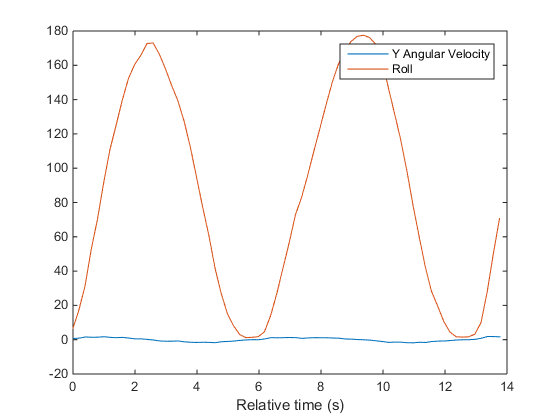

The data is plotted in seconds relative to `mobiledev`'s  `InitialTimestamp` property. This property provides the absolute time of the first data point recorded by a sensor and sent to MATLAB. It acts as the reference point for the timestamps of all sensor data accessed using functions such as `angvellog` and `orientlog`, which are given in seconds relative to `InitialTimestamp`.

## Convert to Absolute Timestamps

To convert all sensor timestamps into absolute timestamps, the `InitialTimestamp` value is converted into a `datetime` object. The individual sensor timestamps, which are in units of seconds, are converted into `seconds`. This simplifies the date arithmetic of turning relative timestamps into absolute timestamps.

tInit = datetime(m.InitialTimestamp,'InputFormat','dd-MM-yyyy HH:mm:ss.SSS');
tAngVel = tInit + seconds(tav);
tOrient = tInit + seconds(to);

## Plot Multiple Sensors Over Absolute Time

Both sensors now have absolute timestamps represented using `datetime`. This makes it easy to visualize the actual time that significant events occurred in sensor readings.

The orientation sensor uses units of degrees, while the angular velocity sensor uses units of radians per second. Before plotting again, `yAngVel` is converted to degrees per second. 

yAngVelDeg = yAngVel * 180/pi;

plot(tAngVel,yAngVelDeg,tOrient,roll);
legend('Y Angular Velocity','Roll');
xlabel('Absolute time (s)');

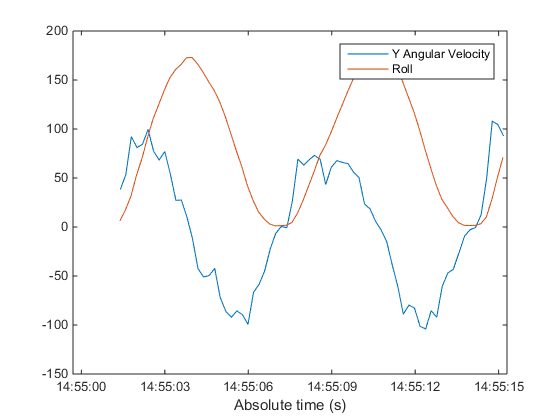

## Clean Up

Turn off the enabled sensors and clear `mobiledev`.

m.AngularVelocitySensorEnabled = 0;
m.OrientationSensorEnabled = 0;

clear m;

*Copyright 2014 The MathWorks, Inc.*